# Design of a Controller for a Minumum Phase  Process with a Finite Delay Term

## Description of the Feedback Control System

Consider the feedback control system described by the block-scheme shown in the following figure   

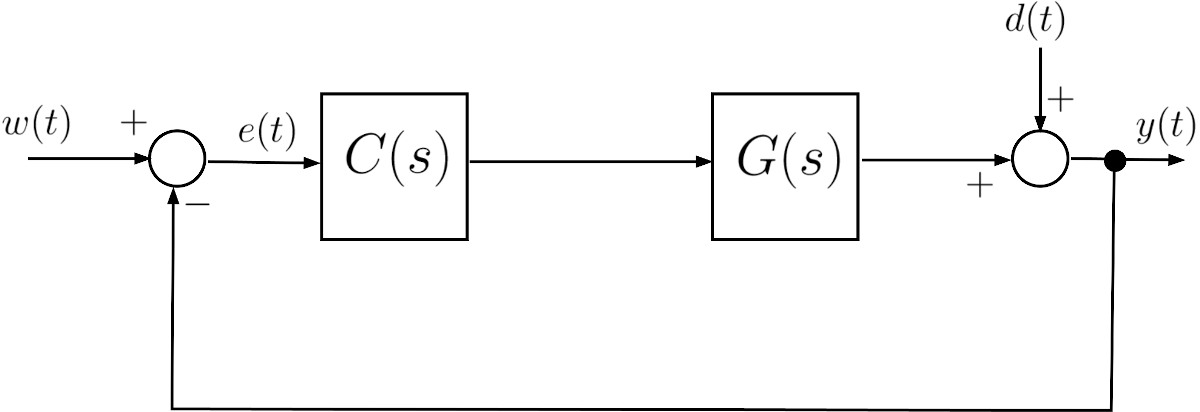	

where $G(s)$ is given by                


$$G(s) = \frac{10}{(1+10\,s)}\,e^{-2s}$$
	

## **Question**		

**Q1**: Design a controller $C(s)$ such that all following requirements are simultaneously met: 

- $\left| e(\infty)\right| =0$ for $w(t) = A\cdot \mathbf{1}(t)$ and $d(t) = B \cdot \mathbf{1}(t)$ $\forall A,\,B \in \mathbb{R}$, where $\mathbf{1}(t)$ denotes the unit step function;

- The crossover angular frequency satisfies $\omega_c \ge 0.5\;\text{rad/s}$; 

- The phase margin satisfies $\varphi_m \ge 30^{\degree}$.

## Foreword to the Provided Solution

The proposed problem admits to more than one possible solution. The proposed solution is not the only admissible solution (in fact, the problem admits to infinite solutions), nor is it optimal. It is only a simple solution that can be obtained using the tools available in MATLAB's Control System Toolbox.

You are encouraged to solve the problem by finding alternative solutions and comparing the performance of the control system using your solution with those obtained using the proposed solution in this live script.  				

## Solution 

Let's define the transfer function of the process $G(s)$ and configure the MATLAB Search Path, by adding the folder containing the M-code able to compute and plot the asymptotic approximation of the Bode diagrams of the frequency response of a given transfer function.

clear

% adding folders (and subfolders) to search path
addpath(genpath('BodeDiagram/'))

% let's define the transfer function builder element
s=tf('s');

Gtilde = 10/(1+10*s); % the process TF WITHOUT THE DELAY TERM
Gs = Gtilde*exp(-2*s) % the complete process TF 

Gs =
 
                 10
  exp(-2*s) * --------
              10 s + 1
 
Continuous-time transfer function.
Model Properties


### A1: Answer to Question Q1

#### The Static Design	

The design of the controller $C(s)$ is carried out by the following logical steps:

First, we notice that the delay term $e^{-2s}$ does not influence the static design, provided that the closed-loop system is asymptotically stable. The designed controller has to ensure the asymptotic stability for the closed-loop system.

To meet Req. (Q1.1), the open-loop transfer function $L(s)$ has to be of type $g \ge 1$. We choose $g=1$ to keep the controller as simple as possible and, more important, to minimise the negative phase contribution that would reduce significantly the phase margin. Since $G(s)$ does not have poles in $0$, the controller $C(s)$ has to provide an integrator:

	
$$C(s) = C_1(s) \cdot C_2(s)\,,\quad C_1(s) = \frac{\mu_C}{s}$$


where $\mu_C$ is a scalar to be designed later on.

Consider a generic angular frequency $\bar \omega$. Compute the magnitude and the phase of the frequency response $G(j\omega)$. We may writte the expressions of magnitude and phase og $G(j \bar \omega)$ as


$$\begin{array}{l}
\left\vert G(j\,\omega) \right\vert = \left\vert \frac{10}{1+10j\omega} \right\vert \cdot \left\vert e^{-2j\bar{\omega}} \right\vert= \left\vert \frac{10}{1+10j\omega} \right\vert = 
\left\vert \tilde{G}(j\,\omega) \right\vert\\
\arg G(j \bar{\omega}) = \arg \left(\frac{10}{1+10j \bar \omega} \right)+ \arg e^{-2j \bar{\omega}} = \arg \tilde{G}(j \bar \omega) + \arg e^{-2j \bar{\omega}}
\end{array}$$
		

where $\tilde{G}(s)$ has been obtained from the process transfer function $G(s)$by neglecting the delay term $e^{-2s}$


$$G(s) = \frac{10}{(1+10\,s)}\,e^{-2s} \quad \Longrightarrow \quad \tilde{G}(s) = \frac{10}{(1+10\,s)}$$
	 

**Important** **Remark**: we could continue and finish the design of the controller using $\tilde{G}(s)$ instead of $G(s)$, but we need to adjust Req.s (Q1.2) and (Q1.3), taking into account the modifications of the open-loop transfer function due to the introduction of $\tilde{G}(s)$.

**Req. (Q1.2)**: The requirement remains unchanged since the term $e^{-2s}$ does not change the crossover frequency $\omega_c$.

**Req. (Q1.3)**: We must modify this requirement, to take into account that in $\tilde{G}(s)$ the presence of the delay teerm $e^{-2s}$ has been neglected. Thus, instead of imposing $\varphi_m \ge 30^{\degree$, we impose 


$$\varphi_m \ge 30^{\degree} +  \left\vert \arg e^{-2j\omega_c} \right\vert \qquad \text{(Q1.3.1)}$$


#### The Dynamic Design

**First Attempt**: $C(s) = C_1(s) \cdot C_2(s)\,,\quad C_1(s) = \frac{\mu_C}{s}\;, \quad C_2(s) = 1$

Is the controller $C(s)$ suitable for fulfilling requirement (Q1.2) and modified requirement (Q1.3.1)?

From requirement (Q1.2), we set $\bar{\omega}=0.5\;\text{rad/s}$ (i.e., the minimum feasible crossover frequency $\omega_c$) and we evaluate the phase, at this angular frequency, of the open-loop frequency response $\tilde{L}(j \omega)$


$$\left. \begin{array}{rcl}
\tilde{L}(j \omega) &=& C(j \omega) \cdot \tilde{G}(j \omega) \\
\bar \omega &=& 0.5 \; \text{rad/s}
\end{array} \right\} \quad \Longrightarrow \quad \tilde{L}(j \bar{\omega}) = \frac{10 \mu_C}{j \bar{\omega} (1+10j \bar{\omega})}$$


Thus


$$\arg \tilde{L}(j \bar{\omega}) = \arg \left(\frac{10 \mu_C}{j \bar{\omega} (1+10j \bar{\omega})} \right) = -90^{\degree}-\arg (1+j5) \approx -90^{\degree}-79^{\degree} = -169^{\degree}$$


According to Req. (Q1.3.1) it should also hold true


$$\arg \tilde{L}(j \bar \omega) = -180^{\degree} + \varphi_m \ge -180^{\degree} + 30^{\degree} + \left\vert \arg e^{-2j\bar{\omega}} \right\vert = 
-150^{\degree} + 2\bar{\omega} \, \frac{180^{\degree}}{\pi} \approx -150^{\degree}+57^{\degree} \;\Longrightarrow \; \arg \tilde{L}(j\bar{\omega}) \approx - 93^{\degree}$$


Clearly, **Req. (Q1.3.1) is not satisfied**, and it is impossible to meet simultaneously Reqs. (Q1.2) and (Q1.3.1) unless we modify $C_2(s)$.

The magnitude and phase Bode diagrams, corresponding to this first design trial, are generated by the following code section. In the figures, the magnitude and the phase of the frequency response, evaluated at the angular frequency $\bar \omega = 0.5\;\text{rad/s}$ respectively neglecting and applying the delay term, are pointed out using markers.

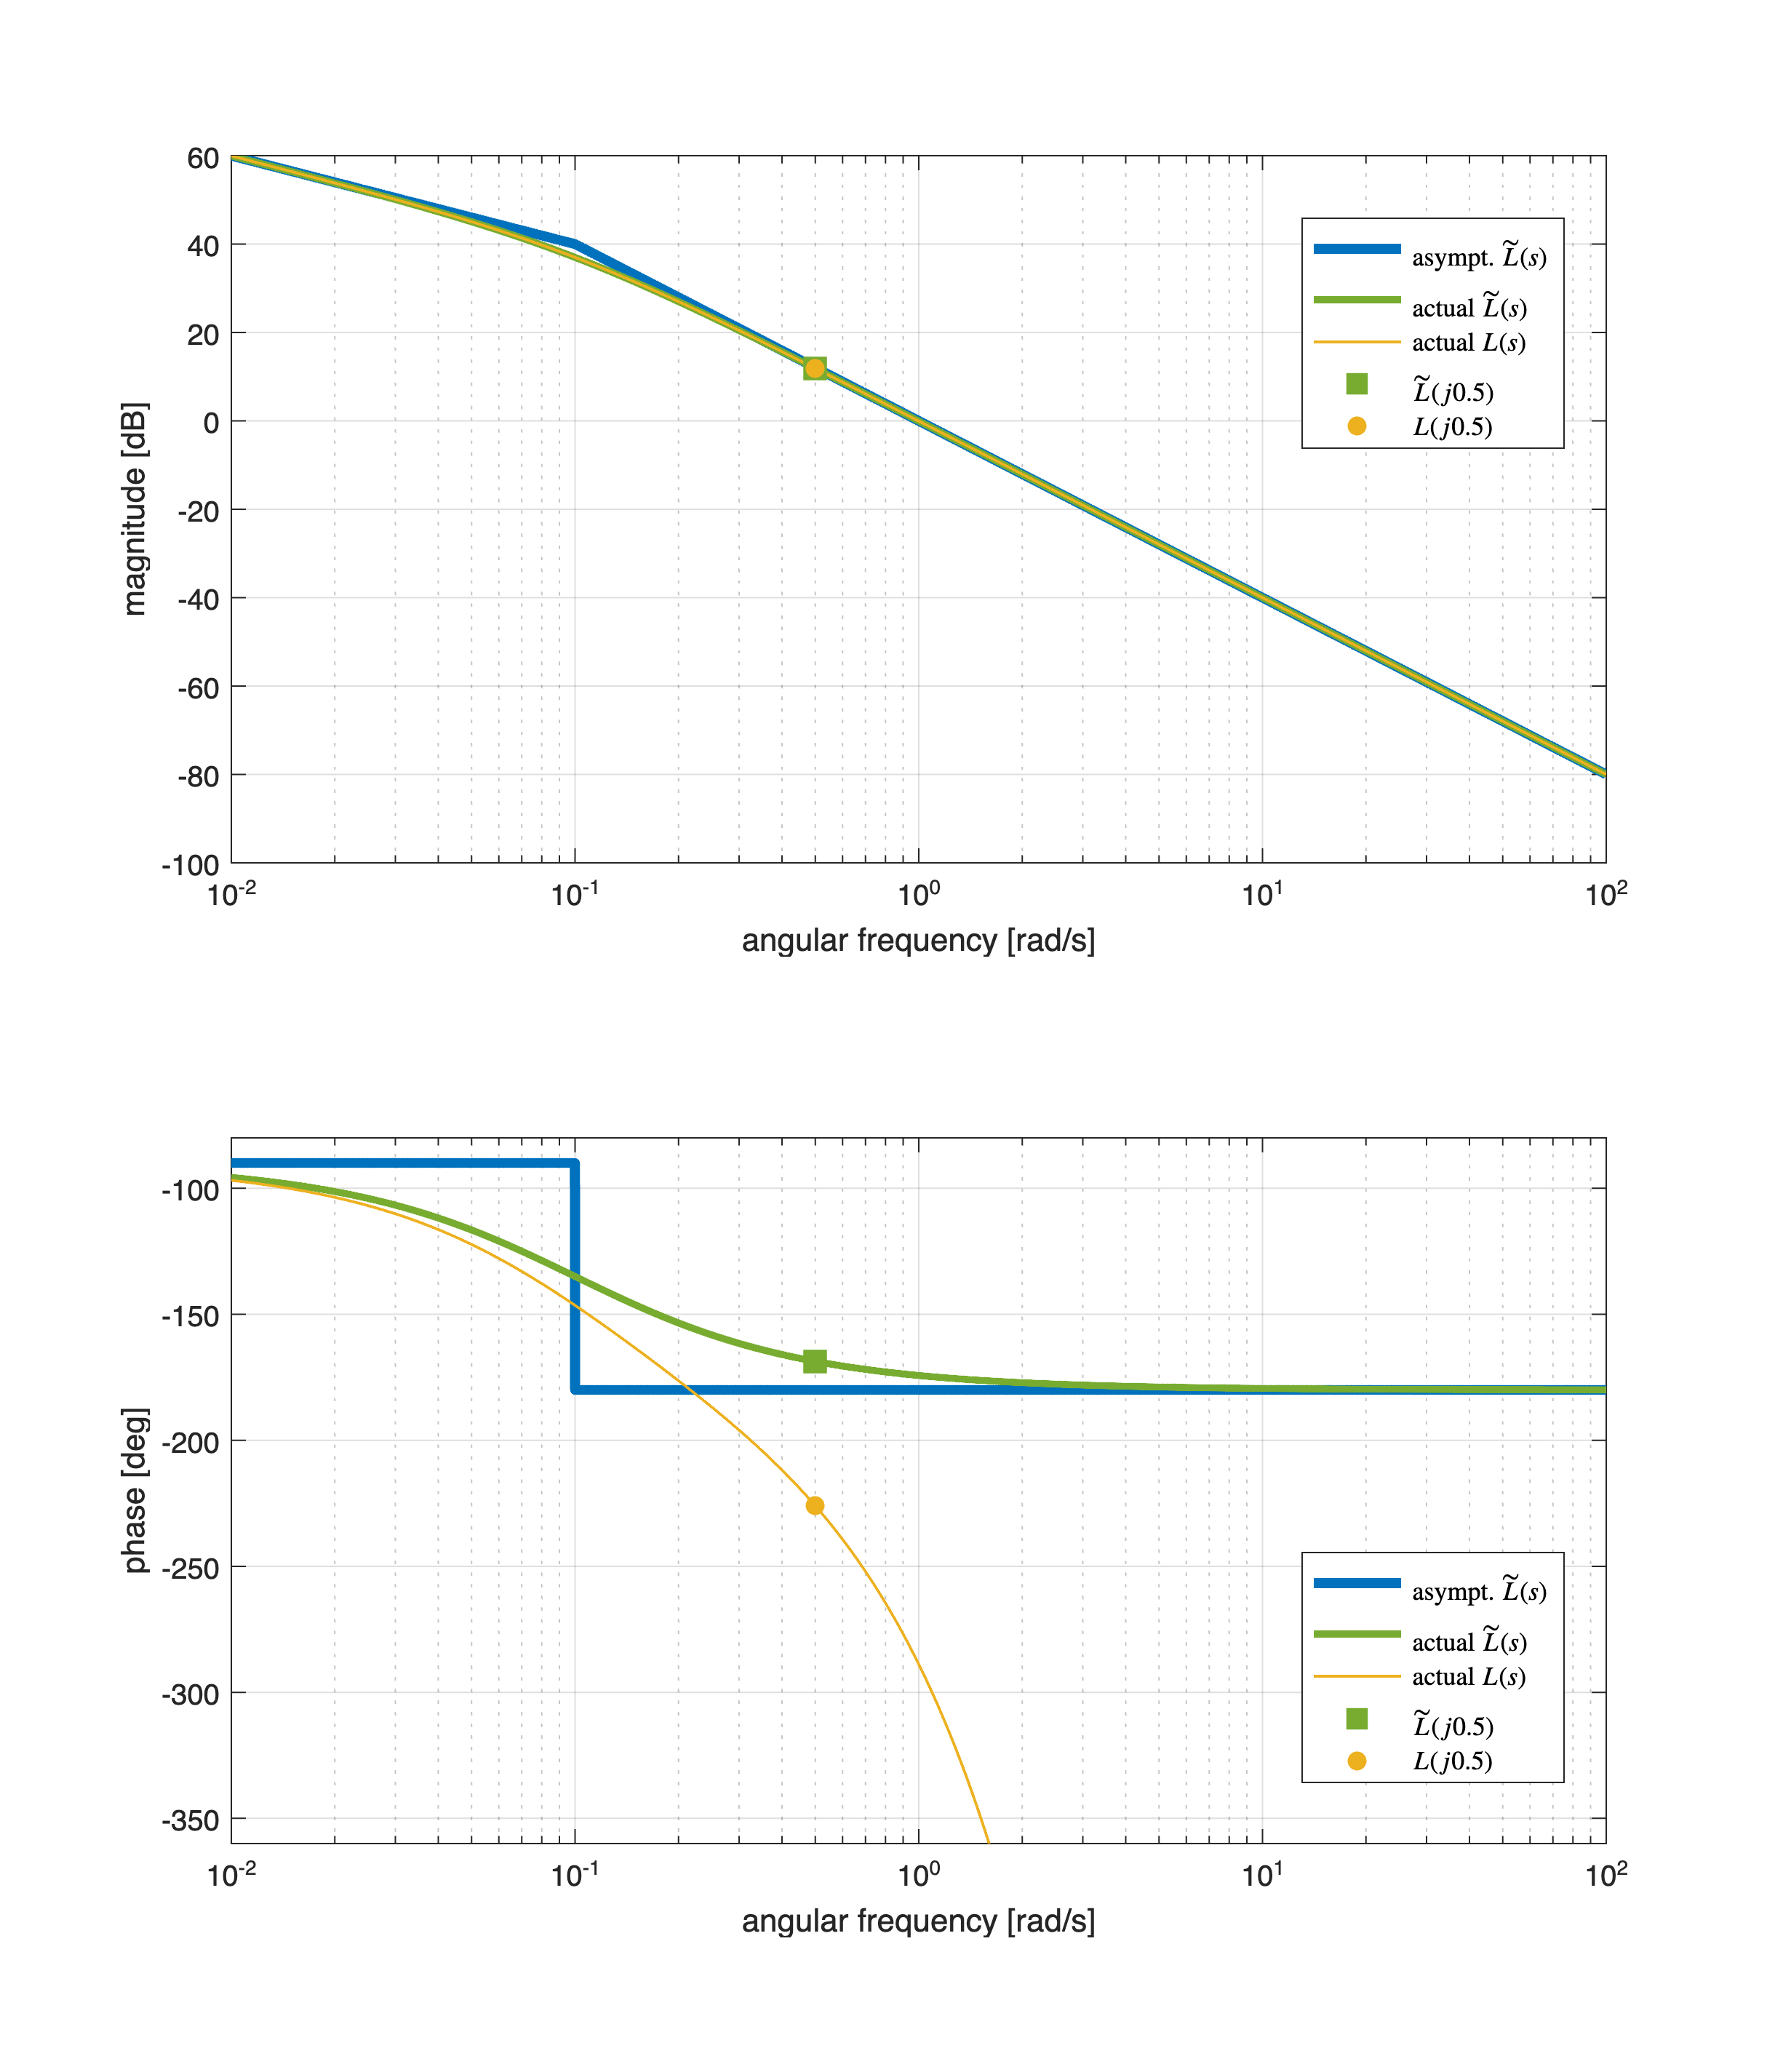

% s=tf('s');
% 
% Gtilde = 10/(1+10*s); % the process TF WITHOUT THE DELAY TERM
% Gs = Gtilde*exp(-2*s) % the complete process TF 

muC = 1;
C1s = muC/s;
C2s = tf(1);
Cs = C1s*C2s;

Ltilde_s = Cs * Gtilde;
Ls = Cs * Gs;

omVALS = logspace(-2,2, 1e4); 
% We want to evaluate the frequency response at 10000 
% angular pulsation values between 10^-1 and 10^2 rad/s.
% 
% ** Note **: 
%    The greater the number of angular pulsation values 
%    used to evaluate the frequency response, the better
%    the accuracy of the graphs of both the asymptotic 
%    and actual diagrams.

% let's create the diagrams: we need to store the handler of the figure 
% refer to the help of drawBodediagrams( )

Bcolors = [0 0.4470 0.7410; ...
           0.9290 0.6940 0.1250; ...
           0.4940 0.1840 0.5560; ...
           0.4660 0.6740 0.1880; ...
           0.3010 0.7450 0.9330; ...
           0.8500 0.3250 0.0980; ...
           0.6350 0.0780 0.1840]; % some different colors 
                                  % for the actual diagrams

hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);

% straight-line approximation and actuual Bode diagrams of Ltilde(s)
[hax1, hax2] = drawBodediagrams(Ltilde_s, omVALS, Bcolors(1, :), 3.5, '-', ...
                       Bcolors(4, :), 2.5, '-', hf);

% actuual Bode diagrams of L(s)
[L_Mag, L_Phase] = bode(Ls, omVALS);
L_Mag_dB = 20*log10(L_Mag(:));
plot(hax1, omVALS, L_Mag_dB, 'Color', Bcolors(2, :),...
     'LineWidth', 1.0, 'LineStyle', '-');
plot(hax2, omVALS, L_Phase(:), 'Color', Bcolors(2, :),...
     'LineWidth', 1.0, 'LineStyle', '-');
ylim(hax2,[-360,  -80]);

% let's eval the frequency response of Ltilde(s) and L(s) at the angular
% frequency bar_omega = 0.5
barOMEGA = 0.5;
FrResp05 = freqresp(Ls, barOMEGA); % freq. resp. L(s)
L05Mag = 20*log10(abs(FrResp05));
L05Phase = rad2deg(angle(FrResp05))-360; % NB to unwrap the angle!

FrRespTilde05 = freqresp(Ltilde_s, barOMEGA); % freq. resp. Ltilde(s)
LTilde05Mag = 20*log10(abs(FrRespTilde05));
LTilde05Phase = rad2deg(angle(FrRespTilde05)); 

% magnitude & phase for Ltilde(j0.5) and L(j0.5)
plot(hax1, barOMEGA, LTilde05Mag, 'Marker','square','MarkerSize',10, ...
      'MarkerEdgeColor',Bcolors(4, :), ...
      'MarkerFaceColor', Bcolors(4, :), ...
      'LineStyle','none');

plot(hax1, barOMEGA, L05Mag, 'Marker','o','MarkerSize',6, ...
      'MarkerEdgeColor',Bcolors(2, :), ...
      'MarkerFaceColor', Bcolors(2, :), ...
      'LineStyle','none');

plot(hax2, barOMEGA, LTilde05Phase, 'Marker','square','MarkerSize',10, ...
      'MarkerEdgeColor',Bcolors(4, :), ...
      'MarkerFaceColor', Bcolors(4, :), ...
      'LineStyle','none');

plot(hax2, barOMEGA, L05Phase, 'Marker','o','MarkerSize',6, ...
      'MarkerEdgeColor',Bcolors(2, :), ...
      'MarkerFaceColor', Bcolors(2, :), ...
      'LineStyle','none');


legend(hax1, 'asympt. $\tilde{L}(s)$', 'actual $\tilde{L}(s)$', ...
             'actual $L(s)$', '$\tilde{L}(j0.5)$', '$L(j 0.5)$',...
             'Interpreter', 'latex', ...
             'Location', 'best');

legend(hax2,  'asympt. $\tilde{L}(s)$', 'actual $\tilde{L}(s)$', ...
             'actual $L(s)$', '$\tilde{L}(j0.5)$', '$L(j 0.5)$',...
             'Interpreter', 'latex', ...
             'Location', 'best');                             

**Second** **Attempt**: The easiest option is to set $C_2(s)$ so as to "cancel" the term $(1+10s)$ at the denominator of $G(s)$. The new controller-candidate transfer function is:


$$\left\{ \begin{array}{rcl}
C_1(s) &=& \frac{\mu_C}{s}\\
C_2(s) &=& (1+10s) \\
C(s) &=& C_1(s) \cdot C_2(s) = \mu_C \, \frac{1+10s}{s}
\end{array} \right. \quad \Longrightarrow \quad 
\tilde{L}(s) = C(s) \cdot \tilde{G}(s) = \frac{10 \mu_C}{s}\,\frac{1+10s}{1+10s} = \frac{10\mu_C}{s}$$


To fulfil requirements Q1.2 and Q1.3.1 simultaneously, we need to find a suitable angular frequency $\bar \omega$


$$\bar{\omega}: \bar{\omega} \ge \frac{1}{2}\,,\quad \arg \tilde{L}(j \bar \omega) \ge -150^{\degree} + 2 \bar{\omega} \, \frac{180^{\degree}}{\pi}$$


On the other hand


$$\tilde{L}(s) =  \frac{10\mu_C}{s} \quad \Longrightarrow \quad 
\arg \tilde{L}(j \bar \omega) = -90^{\degree}$$


We are looking for an angular frequency $\bar \omega$  such that


$$\bar{\omega}: \bar{\omega} \ge \frac{1}{2}\,,\quad -90^{\degree} \ge -150^{\degree} + 2 \bar{\omega} \, \frac{180^{\degree}}{\pi} \quad 
\Longrightarrow \quad
\bar{\omega} \le 60^{\degree}\cdot \frac{\pi}{360^{\degree}} = \frac{\pi}{6} \approx 0.52 \; \text{rad/s}$$


Thus, we set $\omega_c = \bar \omega = \frac{\pi}{6}\;\text{rad/s}$. In this way, both Requirements (Q1.2) and (Q1.3.1) would be met and the design of $C(s)$ has been concluded.

As a last step, we just need to design $\mu_C$ such that $\omega_c = \bar \omega = \frac{\pi}{6}$


$$ \left\vert \frac{10 \mu_C}{s} \right\vert_{s=j \bar{\omega}} =1 \quad \Longrightarrow \quad \frac{10 \, \mu_C}{0.52} = 1 \; 
\Longrightarrow \; \mu_C = \frac{0.52}{10} = 0.052$$


% s=tf('s');
% 
% Gtilde = 10/(1+10*s); % the process TF WITHOUT THE DELAY TERM
% Gs = Gtilde*exp(-2*s) % the complete process TF 

muC = 0.052;
C1s = muC/s;
C2s = (1+10*s);
Cs = C1s*C2s;

Ltilde_s = minreal(Cs * Gtilde)

Ltilde_s =
 
  0.52
  ----
   s
 
Continuous-time transfer function.
Model Properties


Ls = minreal(Cs * Gs)

Ls =
 
              0.52
  exp(-2*s) * ----
               s
 
Continuous-time transfer function.
Model Properties


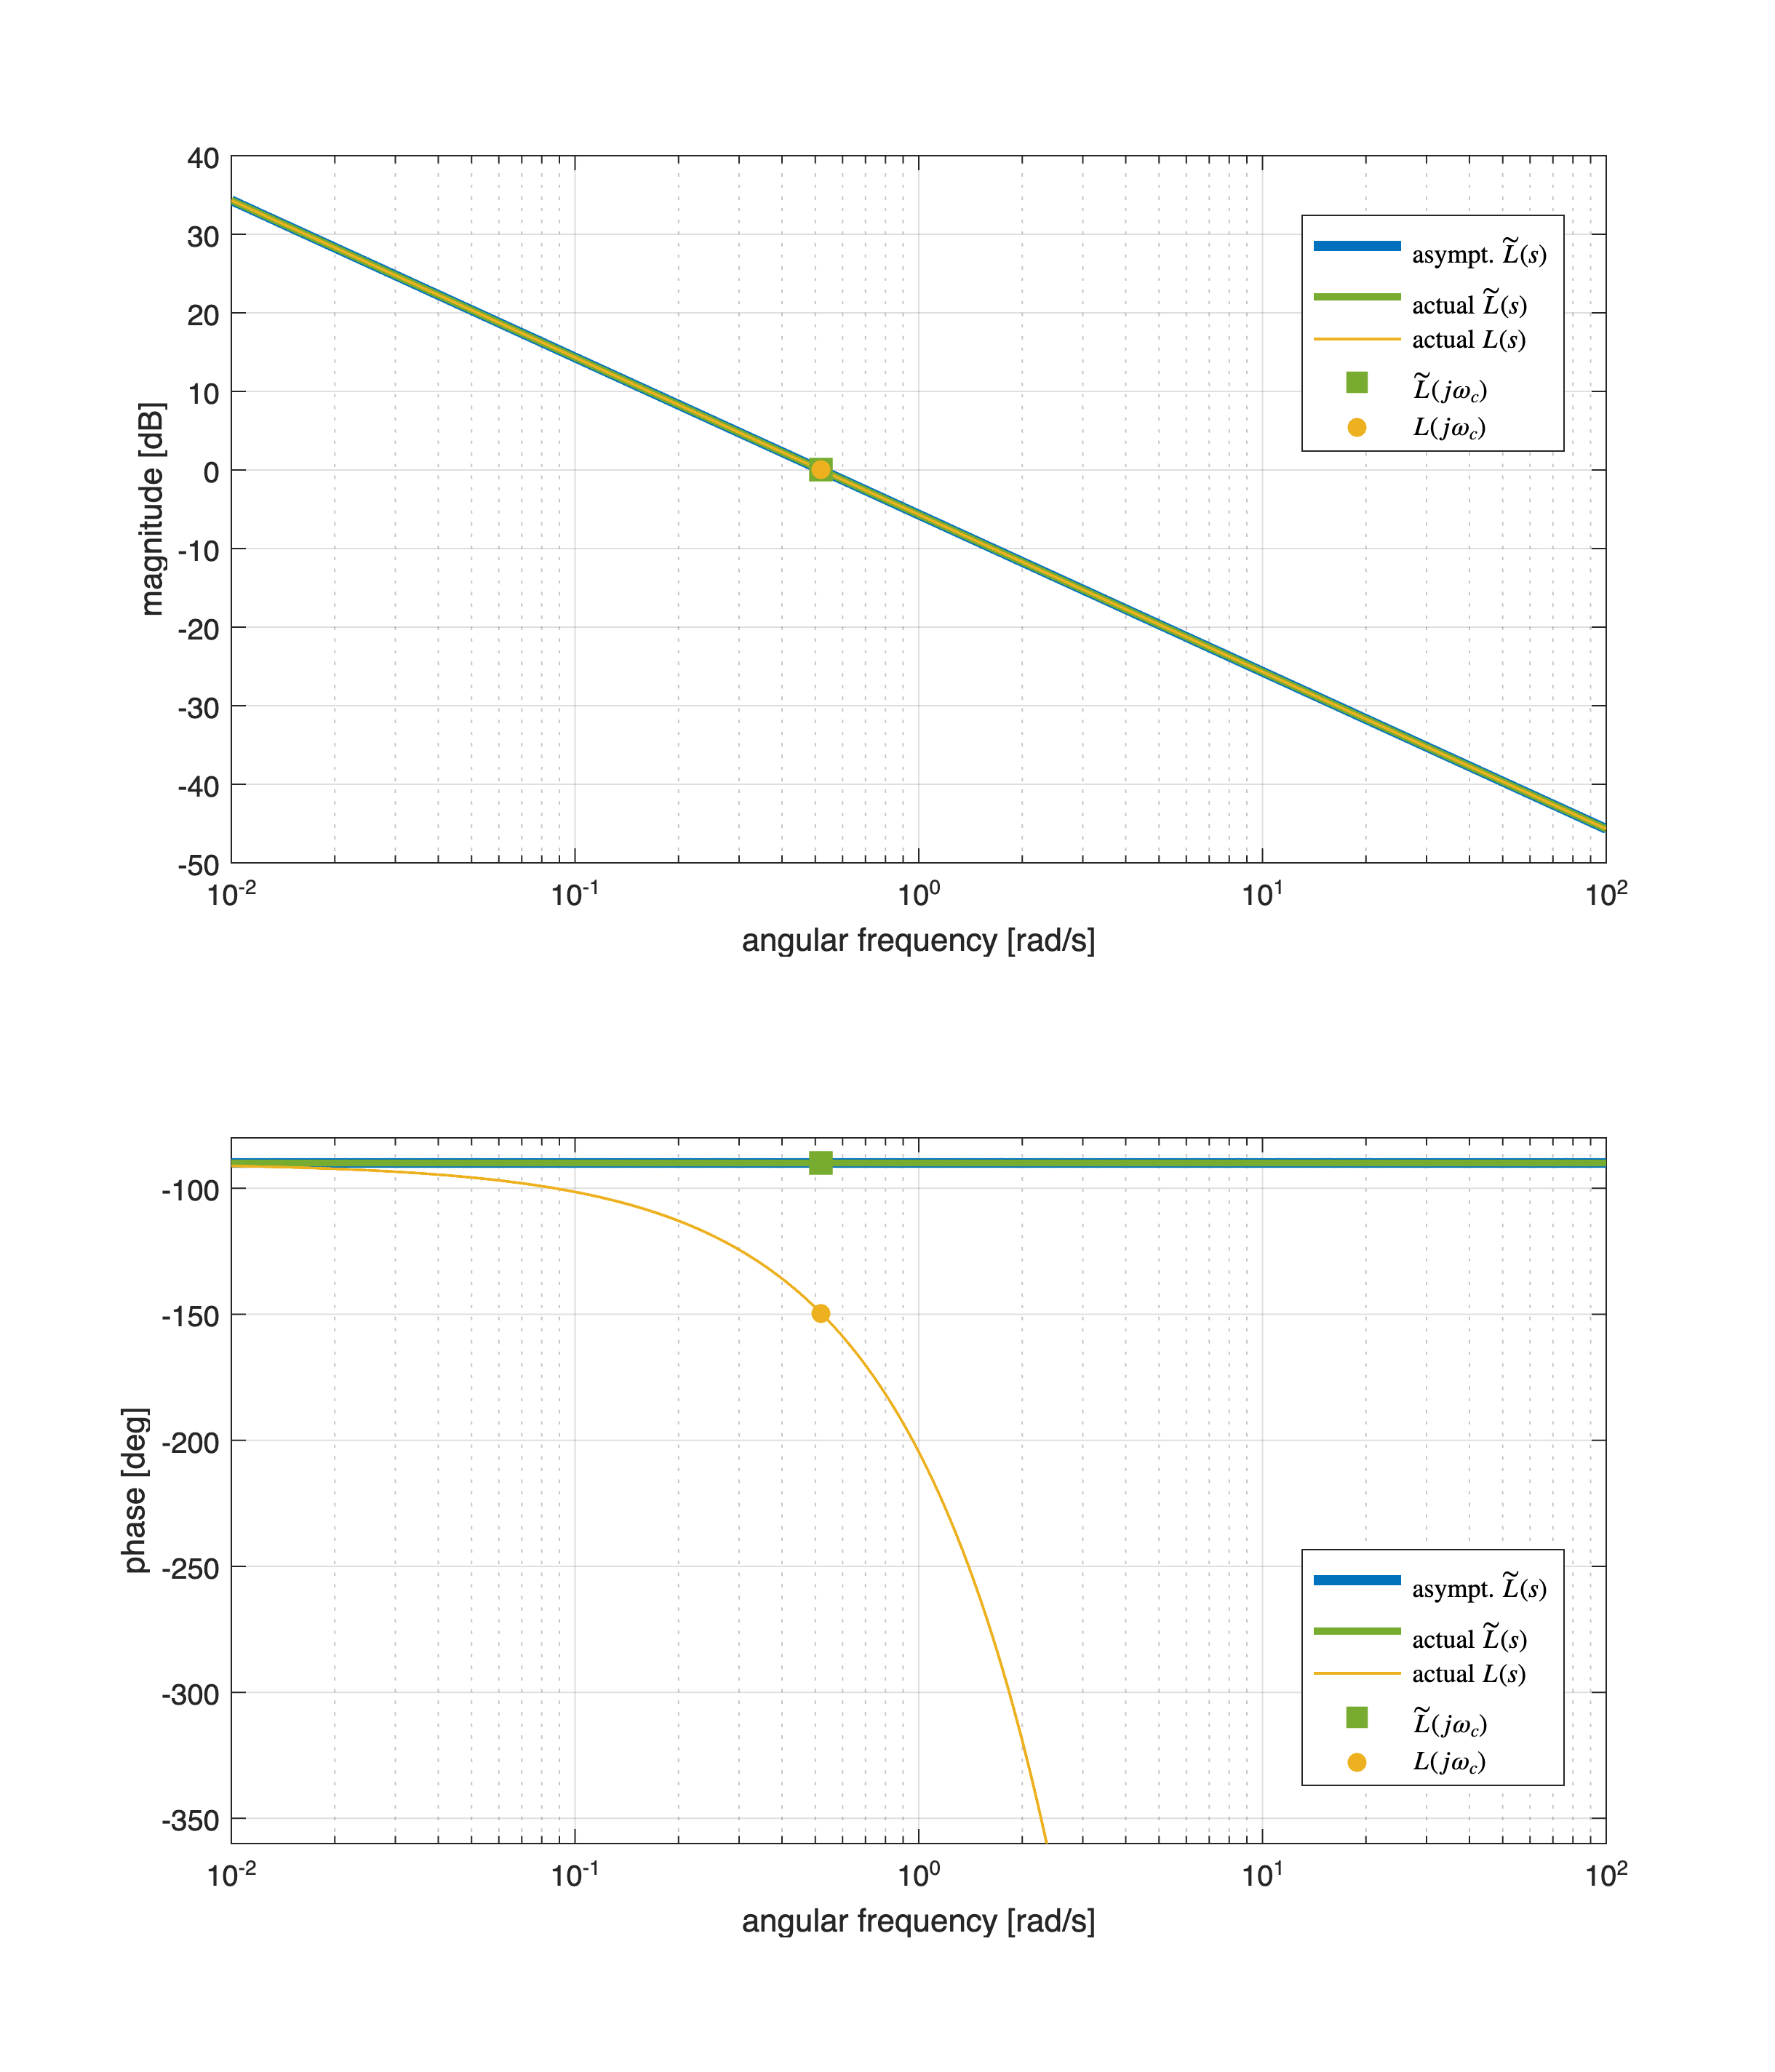


omVALS = logspace(-2,2, 1e4); 
% We want to evaluate the frequency response at 10000 
% angular pulsation values between 10^-1 and 10^2 rad/s.
% 
% ** Note **: 
%    The greater the number of angular pulsation values 
%    used to evaluate the frequency response, the better
%    the accuracy of the graphs of both the asymptotic 
%    and actual diagrams.

% let's create the diagrams: we need to store the handler of the figure 
% refer to the help of drawBodediagrams( )

Bcolors = [0 0.4470 0.7410; ...
           0.9290 0.6940 0.1250; ...
           0.4940 0.1840 0.5560; ...
           0.4660 0.6740 0.1880; ...
           0.3010 0.7450 0.9330; ...
           0.8500 0.3250 0.0980; ...
           0.6350 0.0780 0.1840]; % some different colors 
                                  % for the actual diagrams

hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);

% straight-line approximation and actuual Bode diagrams of Ltilde(s)
[hax1, hax2] = drawBodediagrams(Ltilde_s, omVALS, Bcolors(1, :), 3.5, '-', ...
                       Bcolors(4, :), 2.5, '-', hf);

% actuual Bode diagrams of L(s)
[L_Mag, L_Phase] = bode(Ls, omVALS);
L_Mag_dB = 20*log10(L_Mag(:));
plot(hax1, omVALS, L_Mag_dB, 'Color', Bcolors(2, :),...
     'LineWidth', 1.0, 'LineStyle', '-');
plot(hax2, omVALS, L_Phase(:), 'Color', Bcolors(2, :),...
     'LineWidth', 1.0, 'LineStyle', '-');
ylim(hax2,[-360,  -80]);

% let's eval the frequency response of Ltilde(s) and L(s) at the angular
% frequency bar_omega = 0.5
OMEGAc = 0.52;
FrResp05 = freqresp(Ls, OMEGAc); % freq. resp. L(s)
L05Mag = 20*log10(abs(FrResp05));
L05Phase = rad2deg(angle(FrResp05)); 
FrRespTilde05 = freqresp(Ltilde_s, OMEGAc); % freq. resp. Ltilde(s)
LTilde05Mag = 20*log10(abs(FrRespTilde05));
LTilde05Phase = rad2deg(angle(FrRespTilde05)); 

% magnitude & phase for Ltilde(j0.5) and L(j0.5)
plot(hax1, OMEGAc, LTilde05Mag, 'Marker','square','MarkerSize',10, ...
      'MarkerEdgeColor',Bcolors(4, :), ...
      'MarkerFaceColor', Bcolors(4, :), ...
      'LineStyle','none');

plot(hax1, OMEGAc, L05Mag, 'Marker','o','MarkerSize',6, ...
      'MarkerEdgeColor',Bcolors(2, :), ...
      'MarkerFaceColor', Bcolors(2, :), ...
      'LineStyle','none');

plot(hax2, OMEGAc, LTilde05Phase, 'Marker','square','MarkerSize',10, ...
      'MarkerEdgeColor',Bcolors(4, :), ...
      'MarkerFaceColor', Bcolors(4, :), ...
      'LineStyle','none');

plot(hax2, OMEGAc, L05Phase, 'Marker','o','MarkerSize',6, ...
      'MarkerEdgeColor',Bcolors(2, :), ...
      'MarkerFaceColor', Bcolors(2, :), ...
      'LineStyle','none');


legend(hax1, 'asympt. $\tilde{L}(s)$', 'actual $\tilde{L}(s)$', ...
             'actual $L(s)$', '$\tilde{L}(j \omega_c)$', '$L(j \omega_c)$',...
             'Interpreter', 'latex', ...
             'Location', 'best');

legend(hax2,  'asympt. $\tilde{L}(s)$', 'actual $\tilde{L}(s)$', ...
             'actual $L(s)$', '$\tilde{L}(j \omega_c)$', '$L(j \omega_c)$',...
             'Interpreter', 'latex', ...
             'Location', 'best');                   

#### Fine Tuning of the Controller

Let's import the process $G(s)$ and the controller $C(s)$ transfer functions in the ***Control System Design App***, for a fine tuning.

controlSystemDesigner(Gs, Cs)


As you can note, there is no need for any additional tuning.

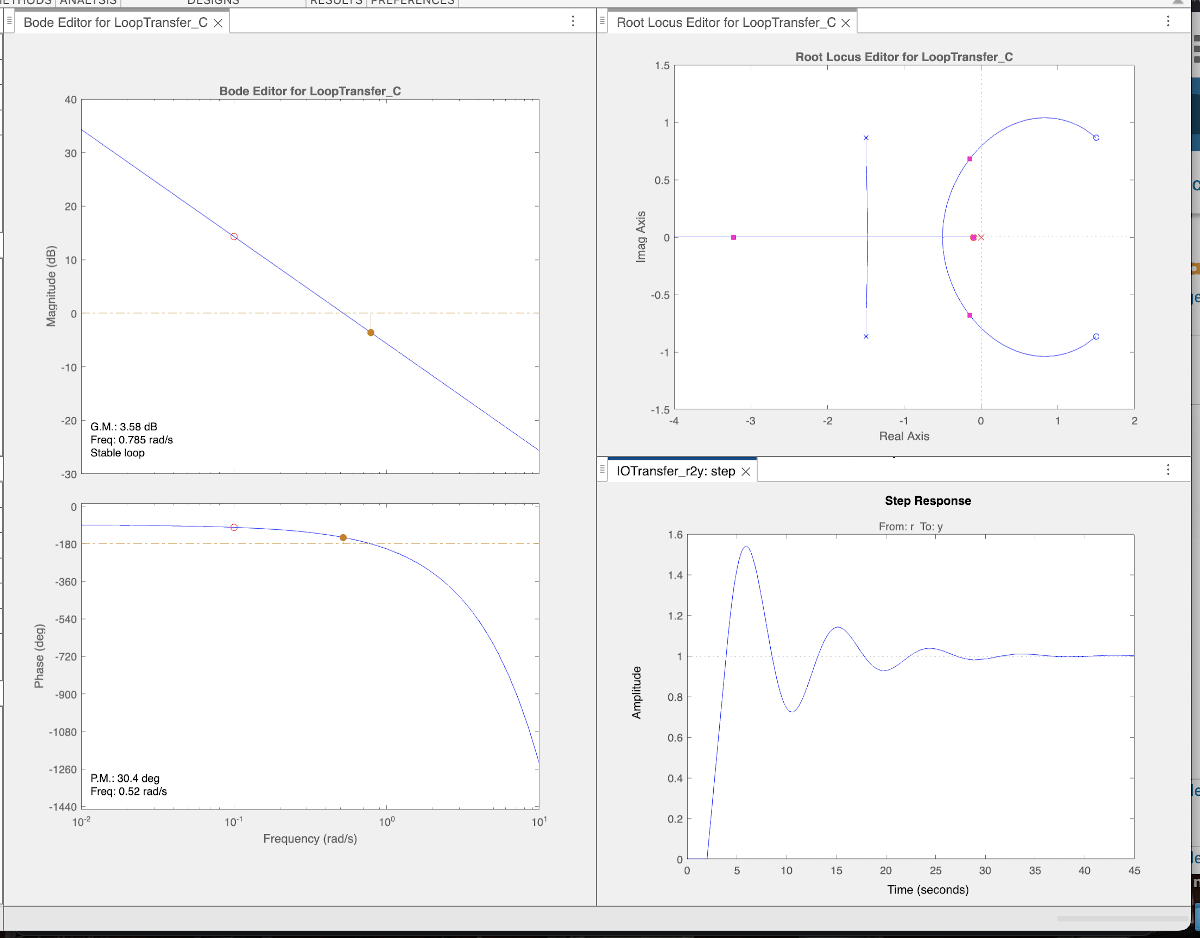

You will find the session data corresponding to the above Figure in the MAT file named `CSD_FOPD_ex1.MAT`	

**Important Remark**: Notice that, as declared in the [MATLAB documentation](https://it.mathworks.com/help/control/ug/compensator-design-for-plant-models-with-time-delays.html), the **tools** of the Control System Designer **supporting** **time** **delays** directly are

- Bode and Nyquist Editor;

- Time Editor Plots;

- Frequency Response Plots

Other **tools** **approximate time delays**. They are, among others

- Root Locus Editor

- Pole/Zero Plots

In fact, in the Root Locus Editor plot, some of the zeros and poles correspond to the Pade'  approximant of the time delay term. For detail, refer to 